clear;close all;
x = importdata("pressure.txt");
X = readmatrix("P_DATA_2.xlsx");

t = x(1:269,1)*4.9/67.25;
s51 = x(1:269,2);
s41 = x(1:269,3);
s31 = x(1:269,4);
s21 = x(1:269,5);
s11 = x(1:269,6);

rs1 = X(15380:15380+49001,1);
rs2 = X(15380:15380+49001,2);
rs4 = X(15380:15380+49001,3);
rs5 = X(15380:15380+49001,4);

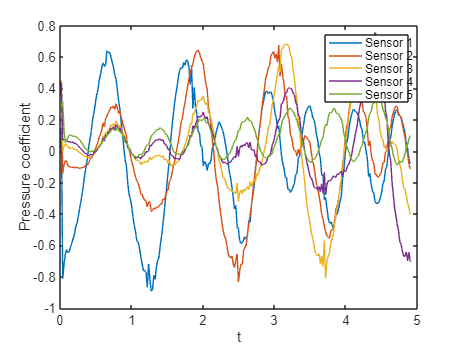

figure("Name","Simulation");
plot(t,s11);
hold on;
plot(t,s21);
hold on;
plot(t,s31);
hold on;
plot(t,s41);
hold on;
plot(t,s51);
legend("Sensor 1","Sensor 2","Sensor 3","Sensor 4","Sensor 5");

xlabel("t");
ylabel("Pressure coefficient");
hold off;

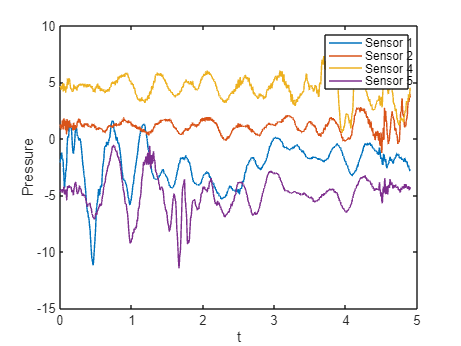

T = linspace(0,4.9,49002);
figure("Name","IRL");
plot(T,rs1);
hold on;
plot(T,rs2);
hold on;
plot(T,rs4);
hold on;
plot(T,rs5);
legend("Sensor 1", "Sensor 2", "Sensor 4", "Sensor 5");

xlabel("t");
ylabel("Pressure");
hold off;

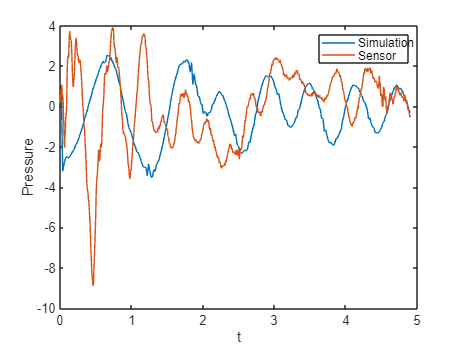

figure("Name","Diff for sensor 1");
plot(t,s11*0.5*1000*0.089*0.089);
hold on;
plot(T,rs1-mean(rs1));

legend("Simulation","Sensor");
xlabel("t");
ylabel("Pressure");
hold off;

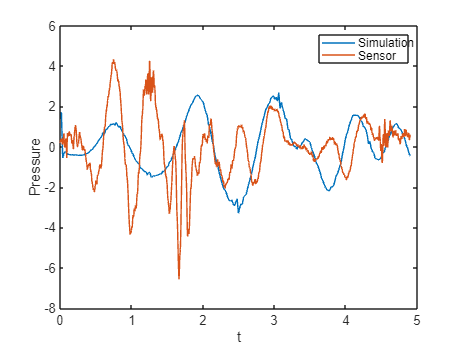

figure("Name","Diff for sensor 2");
plot(t,s21*0.5*1000*0.089*0.089);
hold on;
plot(T,rs5-mean(rs5));

legend("Simulation","Sensor");
xlabel("t");
ylabel("Pressure");
hold off;

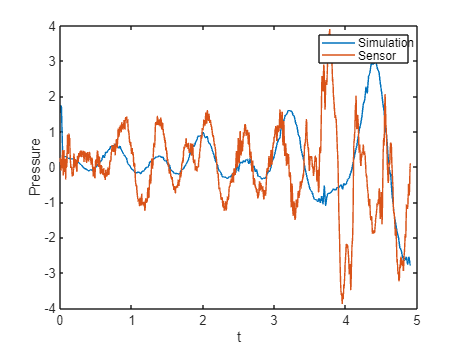

figure("Name","Diff for sensor 4");
plot(t,s41*0.5*1000*0.089*0.089);
hold on;
plot(T,rs4-mean(rs4));

legend("Simulation","Sensor");
xlabel("t");
ylabel("Pressure");
hold off;

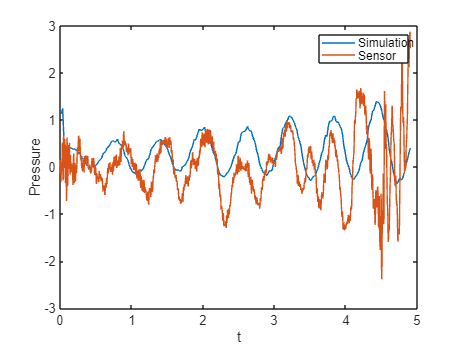

figure("Name","Diff for sensor 5");
plot(t,s51*0.5*1000*0.089*0.089);
hold on;
plot(T,rs2-mean(rs2));

legend("Simulation","Sensor");
xlabel("t");
ylabel("Pressure");
hold off;